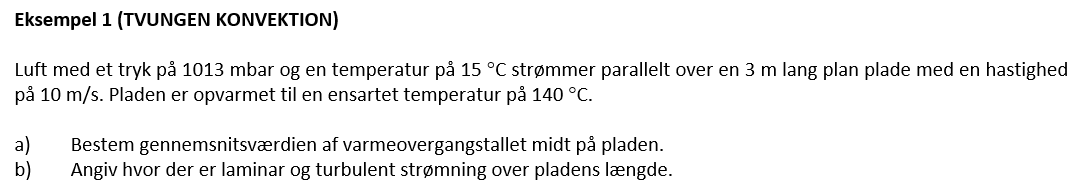

p = 1.013; %tryk

T_luft = 15; %tempereatur
T_plade = 140; %tempereatur
L = 3; %længden af pladen
c = 10; % middelstrømningshastigheden

lambda = 0.0304;%0.0260; % tabel 10.4 i bogen for 20 C

nu = 21.02*1e-6; % Kinematisk viskositet

eta = 20.73*1e-6; % Dynamisk viskositet

c_p = 1.010 *1e3; % Specifik varmekapacite

Re = c * L / nu % Reynolds tal

Re = 1.4272e+06

% ved Re >=5*10^5 har vi turbolent strømning

Pr = eta * c_p / lambda % Prandtls tal

Pr = 0.6887


% NU = 0.664 * sqrt(Re) * Pr^(1/3)  % nussels tal %laminar
NU = (0.037 * Re^(4/5) - 871) * Pr^(1/3)  % nussels tal %turbulent & laminar

NU = 1.9712e+03


alpha = NU * lambda / L % varmeovergangstalllet

alpha = 19.9746

b)

Re = 5*10^5 % her skiftes til turbolunt strømning.

Re = 500000

syms L

% NU = 0.664 * sqrt(Re) * Pr^(1/3)  % nussels tal %laminar
NU = (0.037 * Re^(4/5) - 871) * Pr^(1/3)  % nussels tal %turbulent & laminar

NU = 414.9234

L_turb = vpa(solve(alpha == NU * lambda / L, L),3)

$$L\_turb = 0.631$$